# Estimation of Mobile Orientation using IMU filter

#### **Objective**

In this MATLAB script, we will learn to estimate orientation of a mobile phone using its sensor readings (Accelerometer and Gyroscope) which will be acquired by establishing connection to MATLAB Mobile app.

#### **What is Sensor Fusion**

Sensor Fusion is a term for applications that collect data from multiple sensors (cameras, analog to digital converters etc.) correlate and process it and then use the results to make decisions. In many cases this processing and decision making must be performed in real-time and could result in loss or damage of property if the correct decision is not made in time. Examples of sensor fusion include autonomous vehicles, big science, radar processing, satellite imaging, and 5G beamforming.

#### Applications of Sensor Fusion

Using sensor fusion for real-time data acquisition and processing:

- Autonomous mobile robots can execute repetitive tasks such as moving packages in warehouses, hospitals and airports.

- Unmanned Aerial Vehicles (UAVs) use cameras, LiDars and wide range of sensors (accelerometer, gyroscope, etc.) to enhance the operation of the vehicle or to gather data. UAVs are used in warfare, search and rescue, recreational photography, agriculture, forestry and environmental studies.

#### Connecting to MATLAB Mobile

On you desktop/laptop MATLAB:

- If you have an android phone install **MATLAB Support Package for Android Sensors**

- If you have an iPhone install **MATLAB Support Package for Apple iOS Sensors**

On your mobile phone:

- Install MATLAB Mobile in your phone

- Login to MATLAB mobile using the same credentials as your MATLAB desktop/laptop

On the left top corner of MATLAB Mobile app there is a button which shows the different tabs (Files, Commands, Sensors, etc). Perform the following operations:

- Under **Sensors** > **toggle on Acceleration and Angular Velocity**

- Go to **Sensors **>** Stream to **> **select MATLAB**

- Under** Sensors **> **Sensor Logs** > **Configure** > **(toggle on everything on)**

- Go to **Sensors** > **Sampling parameters** > **set** **Motion Sensors Sample Rate to 10 Hz**

Keep MATLAB mobile open and run the bellow commands

- Clear any existing parameter m

- Initialize connection to MATLAB Mobile with m = mobiledev

clear m

m = mobiledev

m = mobiledev with properties:

                      Device: 'iPhone - iPhone'
                   Connected: 1
                     Logging: 0
            AvailableCameras: {'back' 'front'}
        AvailableMicrophones: {'iPhone Microphone Back' 'iPhone Microphone Bottom' 'iPhone Microphone Front'}
          SelectedMicrophone: 'iPhone Microphone Back'

            InitialTimestamp: '20-Mar-2023 11:00:23.716'

   AccelerationSensorEnabled: 1
AngularVelocitySensorEnabled: 1    (1 Logged values)
       MagneticSensorEnabled: 0
    OrientationSensorEnabled: 0
       PositionSensorEnabled: 0
           MicrophoneEnabled: 0
Show all properties

#### Recording Accelerometer and Gyroscope readings

In MATLAB Mobile:

- Click on START button in the bottom center in Sensors tab

- The Button will turn Red and it will start logging the data of all sensors you have toggled on (here, Accelerometer and Gyroscope)

- Shake the phone a bit to get different acceleration and angular velocity readings

- After 10 seconds click STOP button

- Run the two commands below to acquire the logged Accelerometer and Gyroscope data

gyroscope = m.angvellog

g =    -0.4123    0.0732    0.0400
    0.0108   -0.2794   -0.0282
   -0.0835   -0.0562   -0.0412
   -0.0851   -0.3425    0.0445
   -0.8970   -1.2360   -0.1691
    0.5450   -1.8947    1.3881
    2.4659    1.7147    1.1685
   -0.8161   -0.5705   -0.6087
   -3.2059    1.5688    1.1757
   -0.8110    1.6794    1.1940


accelerometer = m.accellog

a =    -1.3358    5.5202    7.6226
   -0.7850    5.8694    7.5313
   -1.7021    5.0735    8.4043
   -0.7471    5.7930    7.8184
   -1.0745    5.9654    7.1875
    1.4822    5.2256   12.3839
    3.7084    3.9599    3.7831
    1.9046    4.7167    2.6462
   -1.8913    4.3215    4.3193
    2.3536   -0.2796   20.3553


- Accelerometer and Gyroscope sensor data has been collected from the mobile 

#### Fuse Sensor data using IMU filter

- Create an `imufilter` System object with sample rate set to the sample rate of the sensor data. 

- Specify a decimation factor of two to reduce the computational cost of the algorithm.

- Fs = 10 is the Motion Sensor sampling rate we set in MATLAB mobile

d = 2;
Fs = 10;
fuse = imufilter('SampleRate',Fs,'DecimationFactor',decim);

- Pass accelerometer readings and gyroscope readings to the `imufilter` object, `fuse`, to output an estimate of the sensor body orientation over time.

q = fuse(accelerometer,gyroscope);

#### **Visualize the Orientation estimate**

**Orientation** is defined by the angular displacement required to rotate a parent coordinate system to a child coordinate system. 

- Plot the orientation in Euler angles in degrees over time. `imufilter` fusion correctly estimates the change in orientation from an assumed north-facing initial orientation. 

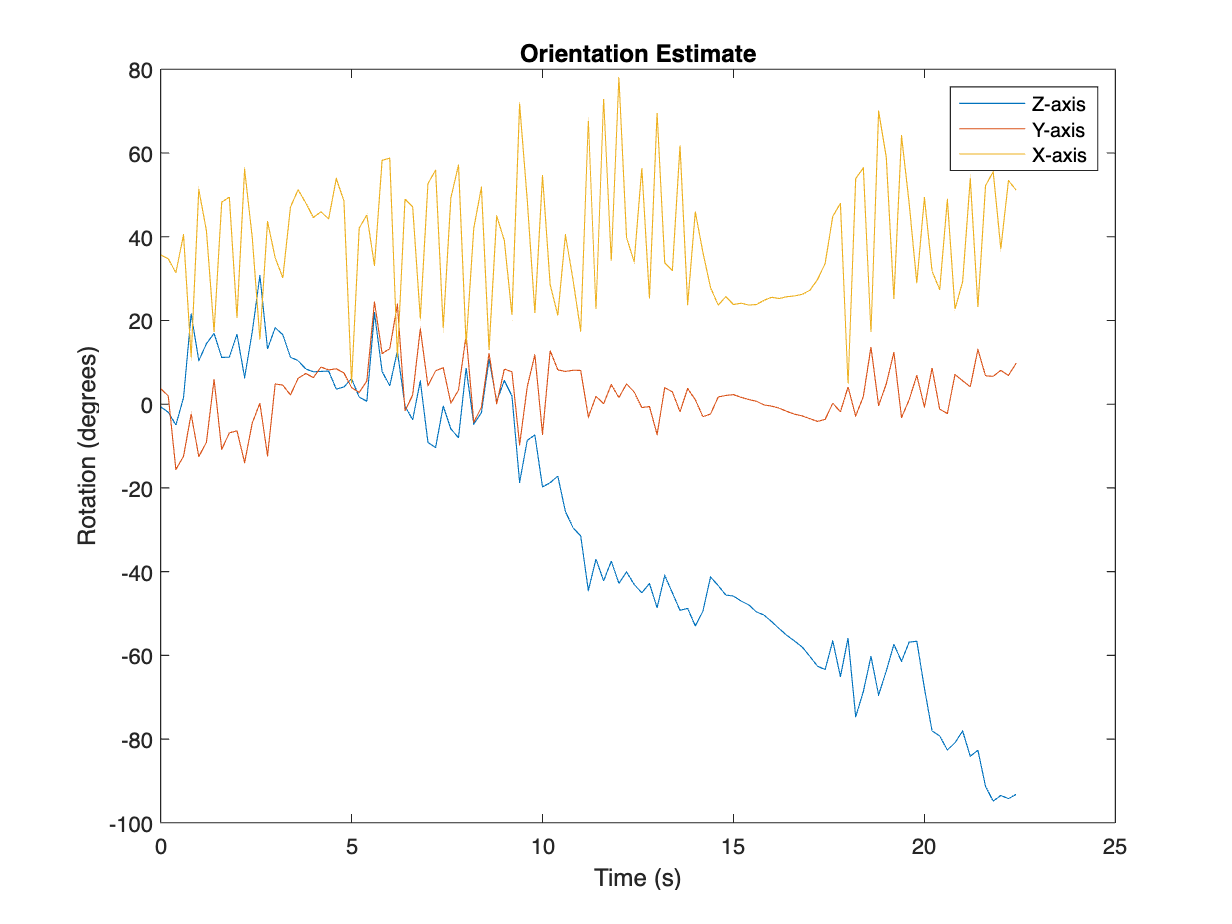

time = (0:decim:size(accelerometer,1)-1)/Fs;

plot(time, eulerd(q,'ZYX','frame'))
title('Orientation Estimate')
legend('Z-axis', 'Y-axis', 'X-axis')
xlabel('Time (s)')
ylabel('Rotation (degrees)')